data = fetch(sln_tissue.RetinaRecon & 'animal_id = 3975', '*');
types = {};
for i =1:numel(data.cell_ids)
    %fetch the cell type
    querystring = sprintf('cell_unid = %d', data.cell_ids(i));
    typedata = fetch(sln_cell.CellEvent * sln_cell.AssignType & querystring, '*');
    event_ids = [typedata.event_id];
    [~, imax] = max(event_ids);
    types{end+1} = typedata(imax).cell_type;
end


m1_indi = strcmp('M1', types);
dm1_indi = strcmp('Displaced M1', types);
cm_indi = [m1_indi;dm1_indi];
notm1_indi = not(any(cm_indi, 1));

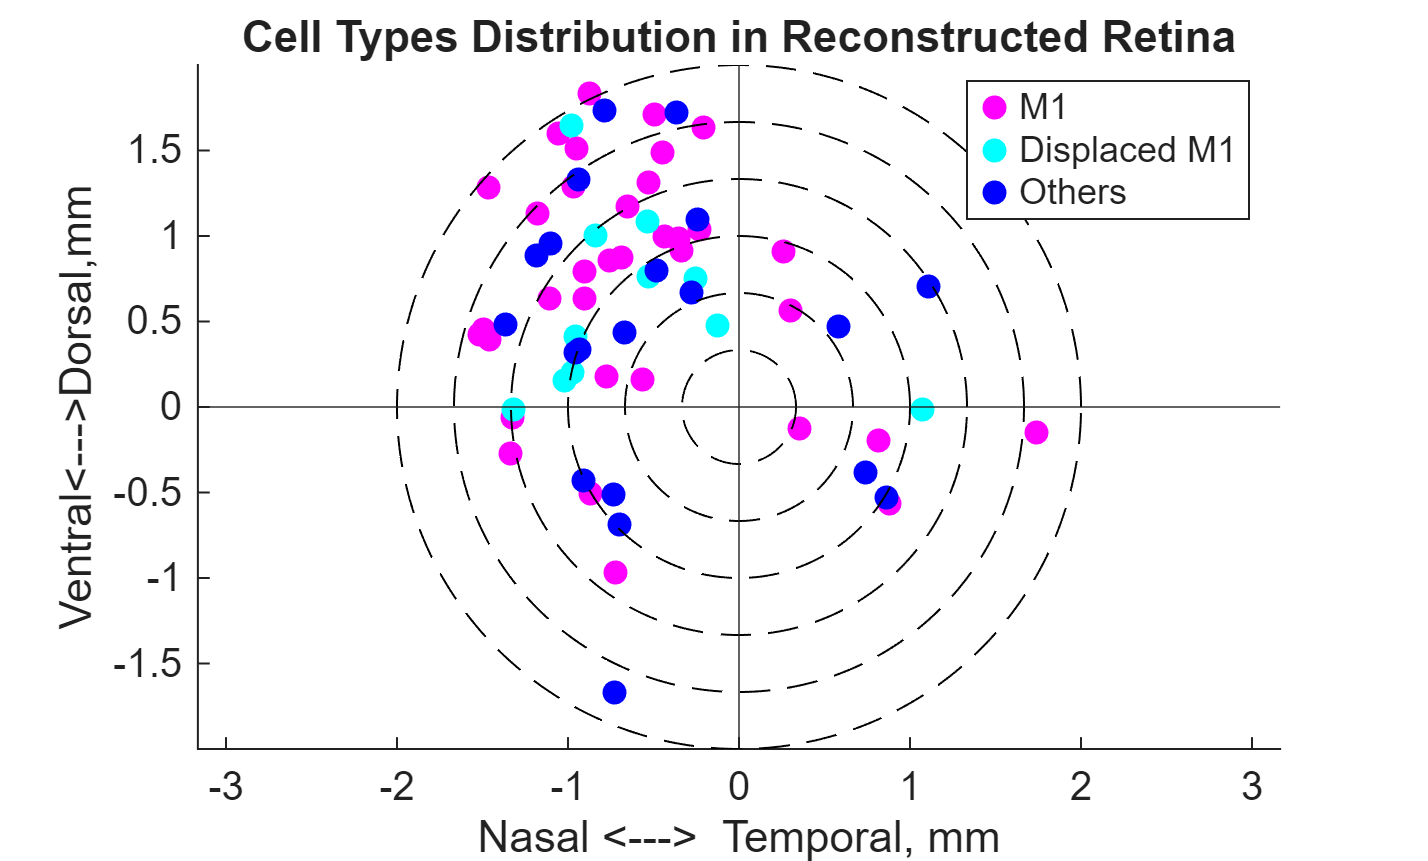


figure();

hold on;
m1x = data.reproj(m1_indi, 1);
m1y =data.reproj(m1_indi, 2);
scatter(m1x, m1y,'magenta', 'filled');

dm1x = data.reproj(dm1_indi, 1);
dm1y = data.reproj(dm1_indi, 2);
scatter(dm1x, dm1y, 'cyan', 'filled');

restx = data.reproj(notm1_indi, 1);
resty = data.reproj(notm1_indi, 2);
scatter(restx, resty, 'blue', 'filled');

nCircles = 6;
% Maximum radius
rMax = 2;
% Radii
radii = linspace(rMax/nCircles, rMax, nCircles);
theta = linspace(0, 2*pi, 500);
for r = radii
    x = r * cos(theta);
    y = r * sin(theta);
    plot(x, y, 'k--');  % dashed black circles
end
xline(0);
yline(0)

xlabel('Nasal <--->  Temporal, mm');
ylabel('Ventral<--->Dorsal,mm');
title('Cell Types Distribution in Reconstructed Retina');
legend({'M1', 'Displaced M1', 'Others'}, 'Location', 'best');
axis equal;
hold off;

%histogram for all RGCs count in retro
mouselist = [3243, 3244, 3249, 3253, 3975, 4197];
celllist =[];
celltypes = {};
for j = 1:numel(mouselist)
    fprintf('processing animal %d...\n', mouselist(j))
    querystr = sprintf('animal_id = %d', mouselist(j));
    cells = fetch(sln_cell.Cell & querystr, '*');
    idlist = [cells.cell_unid];
    celllist = [celllist idlist];
    for k = 1:numel(idlist)
        querystr = sprintf('cell_unid = %d', cells(k).cell_unid);
        tpevents = fetch(sln_cell.CellEvent * sln_cell.AssignType & querystr, '*');
        [~, imax] = max([tpevents.event_id]);
        type = tpevents(imax).cell_type;
        celltypes{end+1} = type;
    end
end

processing animal 3243...
processing animal 3244...
processing animal 3249...
processing animal 3253...
processing animal 3975...
processing animal 4197...


unclas_i = strcmp(celltypes, 'unclassified');
reverse_i = not(unclas_i);
filtered_types = celltypes(reverse_i);

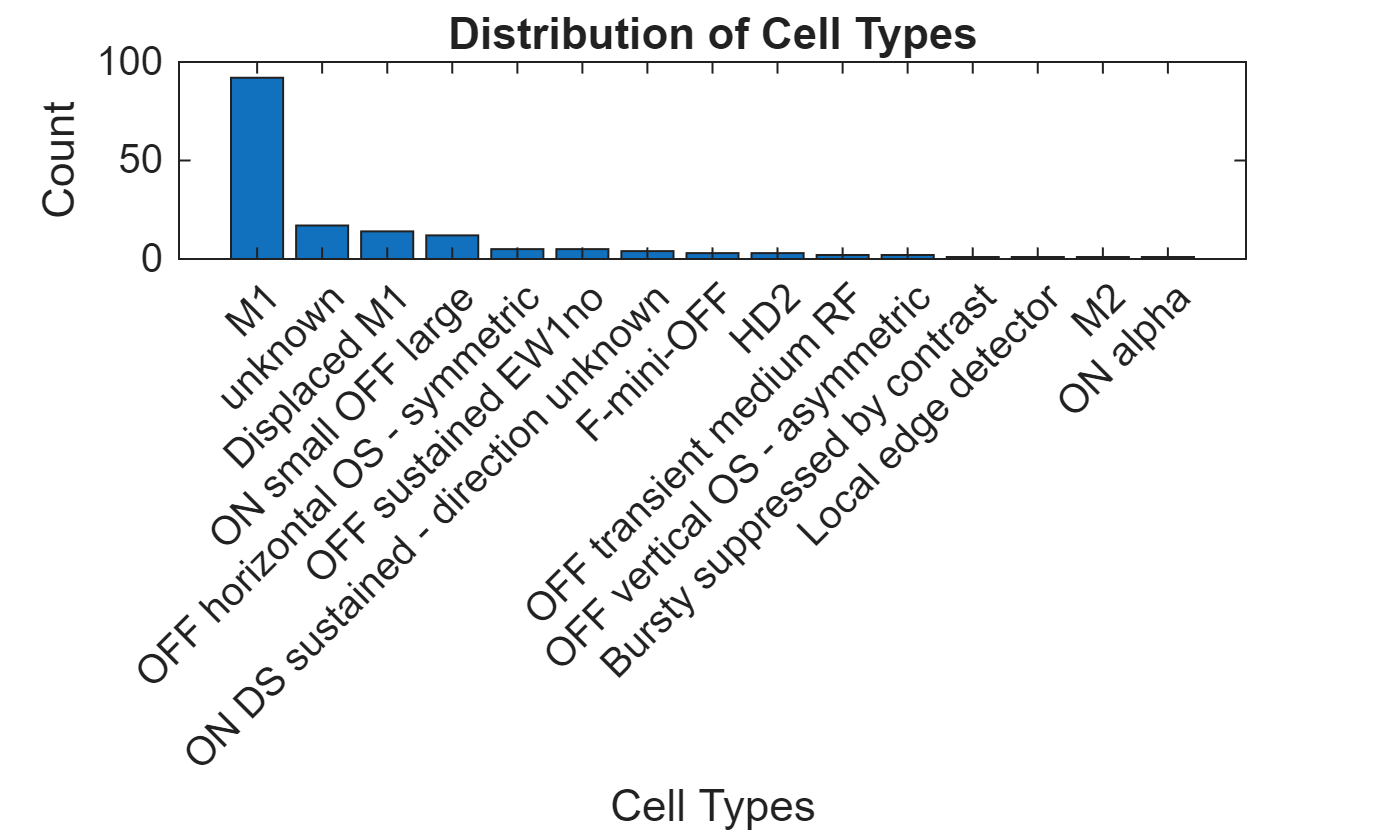


% Create a histogram of cell types
uniqueTypes = unique(filtered_types);
counts = histcounts(categorical(filtered_types), categorical(uniqueTypes));
[sort_counts, sort_idx] = sort(counts, 'descend');
uniqueTypes = uniqueTypes(sort_idx);
%plot a histogram
bar(sort_counts);
set(gca, 'XTickLabel', uniqueTypes, 'XTick', 1:numel(uniqueTypes));
xlabel('Cell Types');
ylabel('Count');
title('Distribution of Cell Types');